## step 50 [deg] simulations for nominal tracking with lqr


% simulate for nominal tracking with lqr

step_amplitude = 50;

data = sim("lab3_ss_lqr_sim_nominal.slx");

t = data.ScopeData1.time;
tetha_h = data.ScopeData1.signals(1).values;  
tetha_d = data.ScopeData1.signals(2).values;
ref_signal = data.ScopeData1.signals(3).values;
% error = data.ScopeData1.signals(3).values;
% command_u =  data.ScopeData1.signals(4).values;

save("data_lab3_50_lq3_nominal.mat",'t','tetha_h','tetha_d','ref_signal');



## Stampa grafico

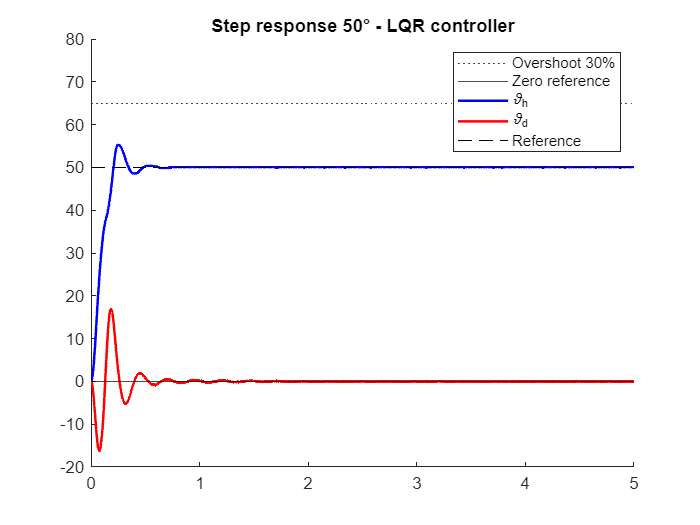


% grafico step 50 deg

load("data_lab3_50_lq3_nominal.mat");
figure;
% plot(t,ref,'k--');
yline(65, 'k:','LineWidth', 0.5, 'DisplayName', 'Overshoot 30%');
yline(0, 'k','LineWidth', 0.5, 'DisplayName', 'Zero reference');
hold on 
plot(t,tetha_h,'b','LineWidth', 1.5, 'DisplayName', '\vartheta_h');
plot(t,tetha_d,'r','LineWidth', 1.5, 'DisplayName', '\vartheta_d');
plot(t,ref_signal,'k--','LineWidth', 0.5, 'DisplayName', 'Reference');
axis([0 5 -20 80])
title('Step response 50° - LQR controller')
legend
hold off

#### Step response parameters


step_50_wind_up_nominal_lqr = stepinfo(tetha_h, t, 50, 'SettlingTimeThreshold', 0.05);
disp(step_50_wind_up_nominal_lqr);

         RiseTime: 0.1577
    TransientTime: 0.3109
     SettlingTime: 0.3109
      SettlingMin: 45.1800
      SettlingMax: 55.2600
        Overshoot: 10.5200
       Undershoot: 0
             Peak: 55.2600
         PeakTime: 0.2440

